datapath = ...
    {"/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Laser_power/20220518_AchsensorHEK002_laser/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Laser_power/20221024_AchsensorHEK002_laser",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Laser_power/20221024_AchsensorHEK003_laser/"...
    }

datapath = 1×3 cell array
    {["/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Laser_power/20220518_AchsensorHEK002_laser/"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Laser_power/20221024_AchsensorHEK002_laser"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Laser_power/20221024_AchsensorHEK003_laser/"]}




StateYao_file = ...
    {"analysis_offset0/20220518_AchsensorHEK002_Analysis2022-09-12.mat",...
    "analysis_offset0/20221024_AchsensorHEK002_Analysis2022-10-25.mat",...
    "Analysis_ROI_Correction_20230803.mat"...
    }

StateYao_file = 1×3 cell array
    {["analysis_offset0/20220518_AchsensorHEK002_Analysis2022-09-12.mat"]}    {["analysis_offset0/20221024_AchsensorHEK002_Analysis2022-10-25.mat"]}    {["Analysis_ROI_Correction_20230803.mat"]}




summary_files = {};

summary_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Laser_power'

summary_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Laser_power'

all_epochs = [2 3 4]; % all the epochs
drug_epochs = [2 3 4];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

CyclePositions = [1 2]

CyclePositions =      1     2


baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

FigureVisible = 'off'

FigureVisible = 'off'

for i = 1:3
    cd(datapath{i})
    load(StateYao_file{i})

    Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
    CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions)
    [lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
    [epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all, FigureVisible)
    currTime = datestr(datetime('now'));
    currTime = currTime(1:11);
    SavedFileName = [stateYao.baseName, '_', currTime,'_', num2str(CyclePositions(1)), '_',num2str(CyclePositions(2)),  '.mat'];
    summary_files{i} = SavedFileName;
    copyfile(SavedFileName, summary_path)
%     save([stateYao.baseName,'topPixels_analysis.mat'],'epoch_response_intensity_norm_all','epoch_response_lft_norm_all','epoch_response_intensity_all','epoch_response_lft_all','lft_all','intensity_all', 'EpochStartAcq_all', 'AcqTime_all')
end

epoch_response_intensity_norm_all = 1×2 cell array
    {2×3 double}    {2×3 double}


epoch_response_lft_norm_all = 1×2 cell array
    {2×3 double}    {2×3 double}


epoch_response_intensity_all = 1×2 cell array
    {2×3 double}    {2×3 double}


epoch_response_lft_all = 1×2 cell array
    {2×3 double}    {2×3 double}


epoch_response_intensity_norm_all = 1×2 cell array
    {2×4 double}    {2×4 double}


epoch_response_lft_norm_all = 1×2 cell array
    {2×4 double}    {2×4 double}


epoch_response_intensity_all = 1×2 cell array
    {2×4 double}    {2×4 double}


epoch_response_lft_all = 1×2 cell array
    {2×4 double}    {2×4 double}


epoch_response_intensity_norm_all = 1×2 cell array
    {2×5 double}    {2×5 double}


epoch_response_lft_norm_all = 1×2 cell array
    {2×5 double}    {2×5 double}


epoch_response_intensity_all = 1×2 cell array
    {2×5 double}    {2×5 double}


epoch_response_lft_all = 1×2 cell array
    {2×5 double}    {2×5 double}



cd(summary_path)
save('summary_files.mat', 'summary_files')

summary_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Laser_power'

summary_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Laser_power'

cd(summary_path)
load('summary_files.mat')

lft_response_all_low = [];
intensity_response_all_low = [];
lft_response_all_high = [];
intensity_response_all_high = [];


for i = 1:length(summary_files)
    load(summary_files{i});
    lft_response_all_low = [lft_response_all_low epoch_response_lft_all{1} NaN(2,1)];
    intensity_response_all_low = [intensity_response_all_low epoch_response_intensity_all{1} NaN(2,1)];
    lft_response_all_high = [lft_response_all_high epoch_response_lft_all{2} NaN(2,1)];
    intensity_response_all_high = [intensity_response_all_high epoch_response_intensity_all{2} NaN(2,1)];
end

save('summary_data.mat', 'lft_response_all_low', 'intensity_response_all_low', 'lft_response_all_high', 'intensity_response_all_high')

lft_response_change_all_low = [];
intensity_response_change_all_low = [];
lft_response_change_all_high = [];
intensity_response_change_all_high = [];


for i = 1:length(summary_files)
    load(summary_files{i});
    lft_response_change_all_low = [lft_response_change_all_low epoch_response_lft_norm_all{1} NaN(2,1)];
    intensity_response_change_all_low = [intensity_response_change_all_low epoch_response_intensity_norm_all{1} NaN(2,1)];
    lft_response_change_all_high = [lft_response_change_all_high epoch_response_lft_norm_all{2} NaN(2,1)];
    intensity_response_change_all_high = [intensity_response_change_all_high epoch_response_intensity_norm_all{2} NaN(2,1)];
end

acq = 10

acq = 10

mask = stateYao.I_ROI_stack_TopPixels{1,1}{acq}{1};
Lifetime_map = stateYao.images.origData.lifetimeMaps{1,1}(:,:,acq)

Lifetime_map =     4.1357    2.9082    4.0382    4.9001    3.8600    4.4952    2.5408         0    2.2965    7.2803         0         0    2.1010         0    2.1010    1.3192    3.0782         0         0         0         0         0         0         0    2.5408    6.0588    2.7851         0    6.3763         0         0    2.3453    3.5864    9.7233   10.2119    4.6906    5.1304         0    3.1515    4.5441         0    4.3975    5.3991    5.9855    4.7558         0    1.4170    2.5245    3.4203    6.1320
    3.7928    4.3784    3.4924    2.9642    4.8861    4.8698    2.4919    1.6124    9.0881    4.0310         0    5.6190    1.6124         0         0         0         0    6.4496    5.6434         0         0    3.8112         0         0    1.5961    3.2493    2.2476         0         0    2.8339    3.2411    2.1010    1.9544         0    2.8828    7.4269    2.7036    4.9594         0         0         0    7.8666         0    2.1743    3.6548    3.1027    3.1922    1.8079    

spc.lifetimeMaps{1,1} - Lifetime_map

ans =     0.4397    0.4397    0.4397    0.4397    0.4397    0.4397    0.4397         0    0.4397    0.4397         0         0    0.4397         0    0.4397    0.4397    0.4397         0         0         0         0         0         0         0    0.4397    0.4397    0.4397         0    0.4397         0         0    0.4397    0.4397    0.4397    0.4397    0.4397    0.4397         0    0.4397    0.4397         0    0.4397    0.4397    0.4397    0.4397         0    0.4397    0.4397    0.4397    0.4397
    0.4397    0.4397    0.4397    0.4397    0.4397    0.4397    0.4397    0.4397    0.4397    0.4397         0    0.4397    0.4397         0         0         0         0    0.4397    0.4397         0         0    0.4397         0         0    0.4397    0.4397    0.4397         0         0    0.4397    0.4397    0.4397    0.4397         0    0.4397    0.4397    0.4397    0.4397         0         0         0    0.4397         0    0.4397    0.4397    0.4397    0.4397    0.4397    0.4397   

global offset fixedoffset
fixedoffset=1;
% offset=spc.switchess{1}.figOffset;
offset=0.439748201519251;

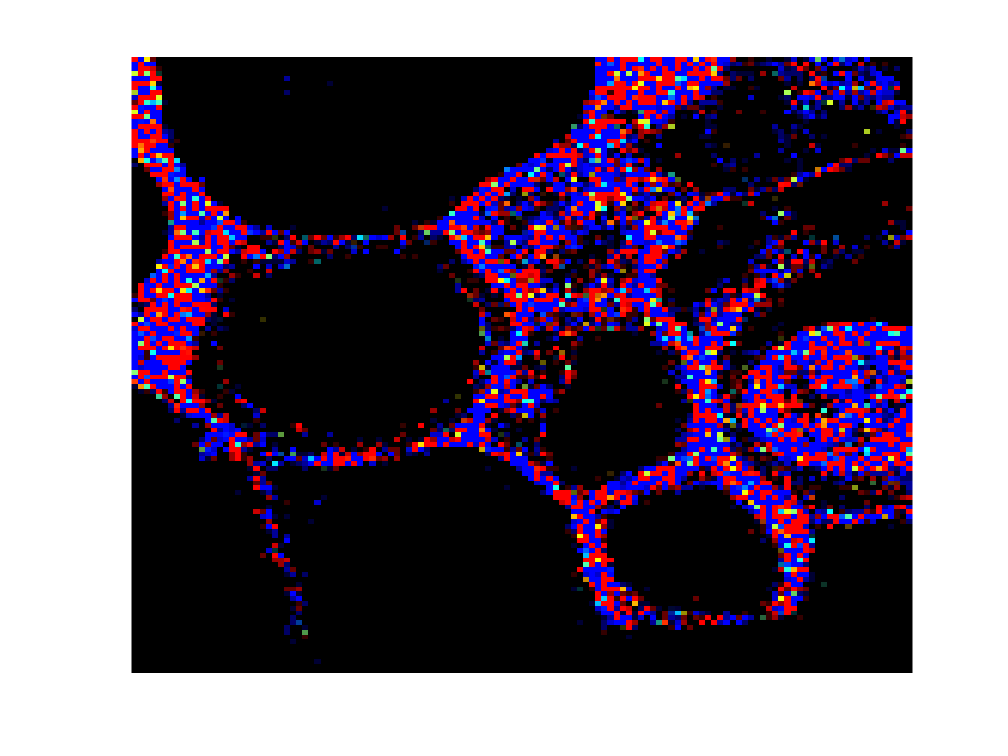

% low laser power, baseline, acq_num = 24

cyclePosition1_num = 10;

intensity_map = stateYao.images.origData.projects{1,1}(:,:,cyclePosition1_num);
Lifetime_rgb_map_24 = spc.rgbLifetimes{1};

figure
image(Lifetime_rgb_map_24);
axis off;


figure
h=heatmap(intensity_map);
h.Colormap=gray

h =   HeatmapChart with properties:

        XData: {128×1 cell}
        YData: {128×1 cell}
    ColorData: [128×128 double]

  Show all properties


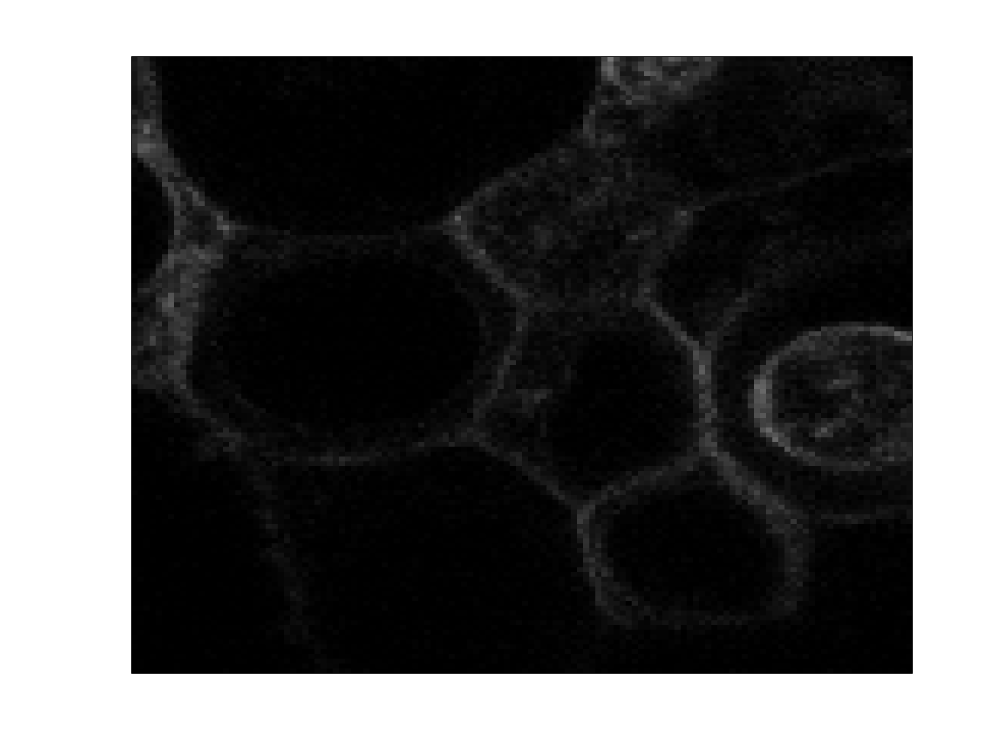

Ax=gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
h.ColorbarVisible='off';
h.GridVisible='off';
h.ColorLimits=[0 150];

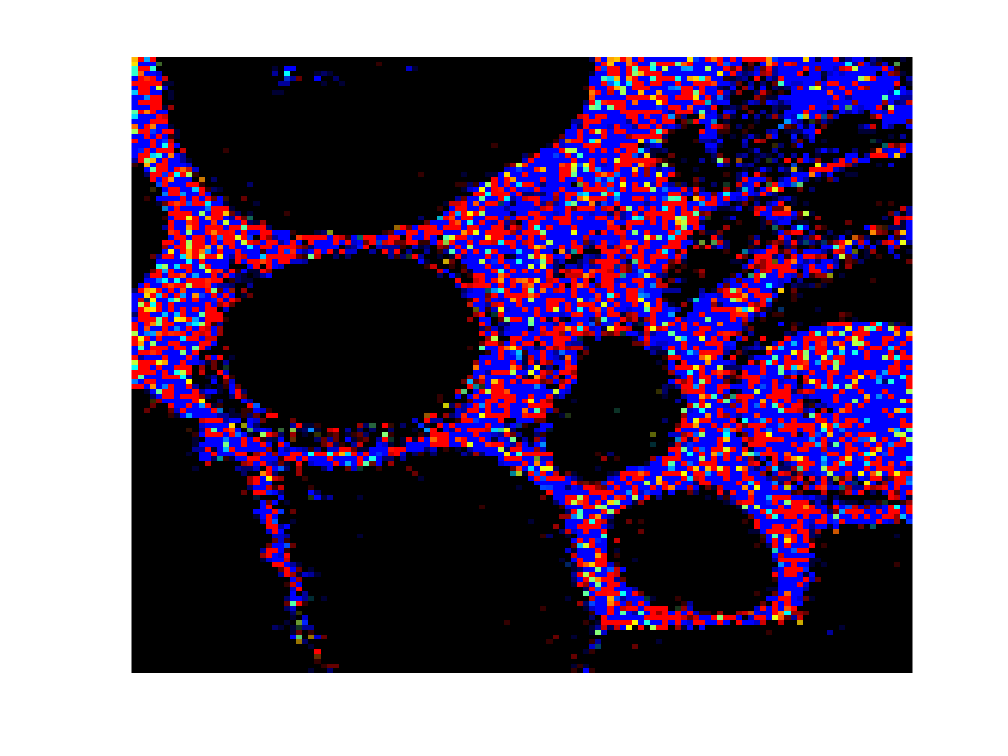

% high laser power, baseline, acq_num = 25

cyclePosition2_num = 10;

intensity_map = stateYao.images.origData.projects{2,1}(:,:,cyclePosition2_num);
Lifetime_rgb_map_25 = spc.rgbLifetimes{1};

figure
image(Lifetime_rgb_map_25);
axis off;


figure
h=heatmap(intensity_map);
h.Colormap=gray

h =   HeatmapChart with properties:

        XData: {128×1 cell}
        YData: {128×1 cell}
    ColorData: [128×128 double]

  Show all properties


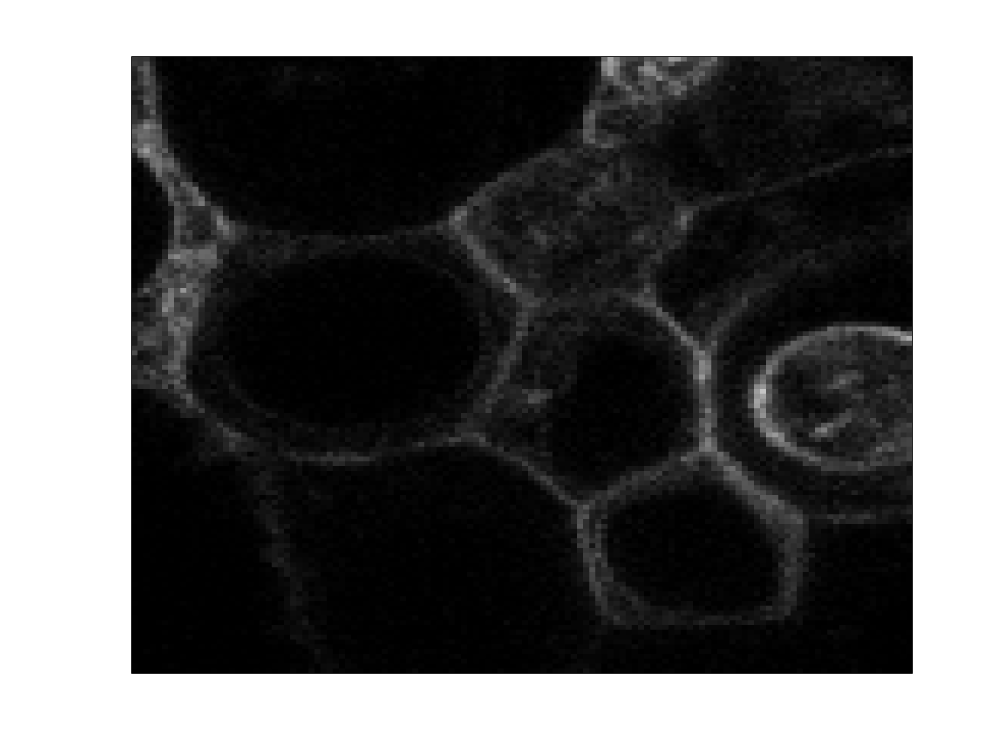

Ax=gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
h.ColorbarVisible='off';
h.GridVisible='off';
h.ColorLimits=[0 150];

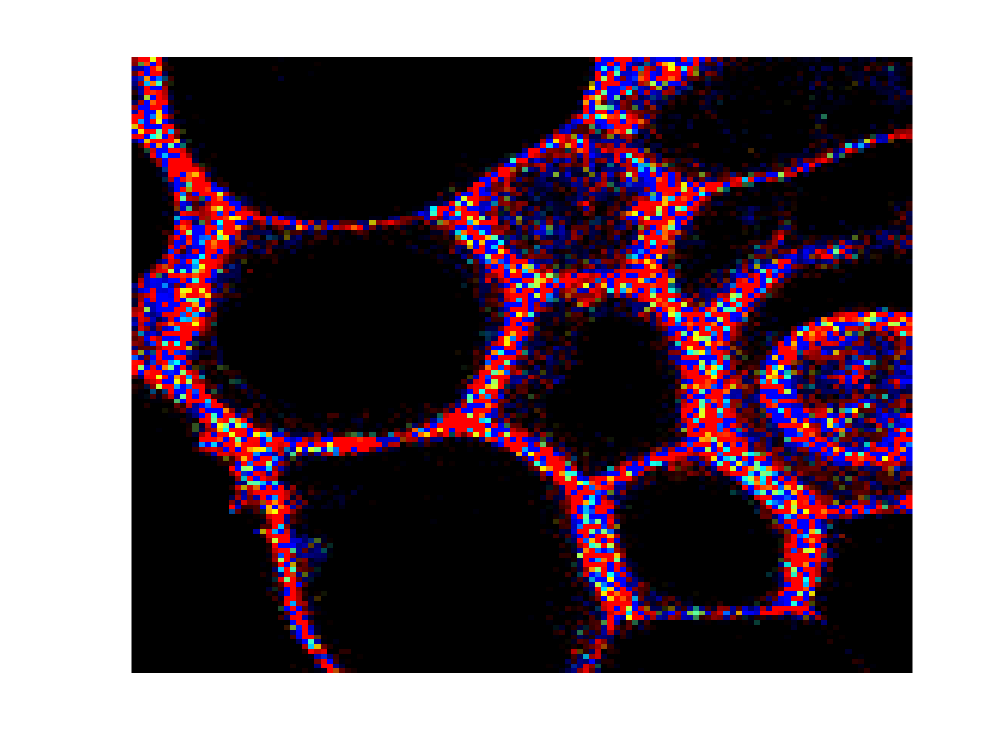

% low laser power, ACh, acq_num = 80

cyclePosition1_num = 38;

intensity_map = stateYao.images.origData.projects{1,1}(:,:,cyclePosition1_num);
Lifetime_rgb_map_80 = spc.rgbLifetimes{1};

figure
image(Lifetime_rgb_map_80);
axis off;


figure
h=heatmap(intensity_map);
h.Colormap=gray

h =   HeatmapChart with properties:

        XData: {128×1 cell}
        YData: {128×1 cell}
    ColorData: [128×128 double]

  Show all properties


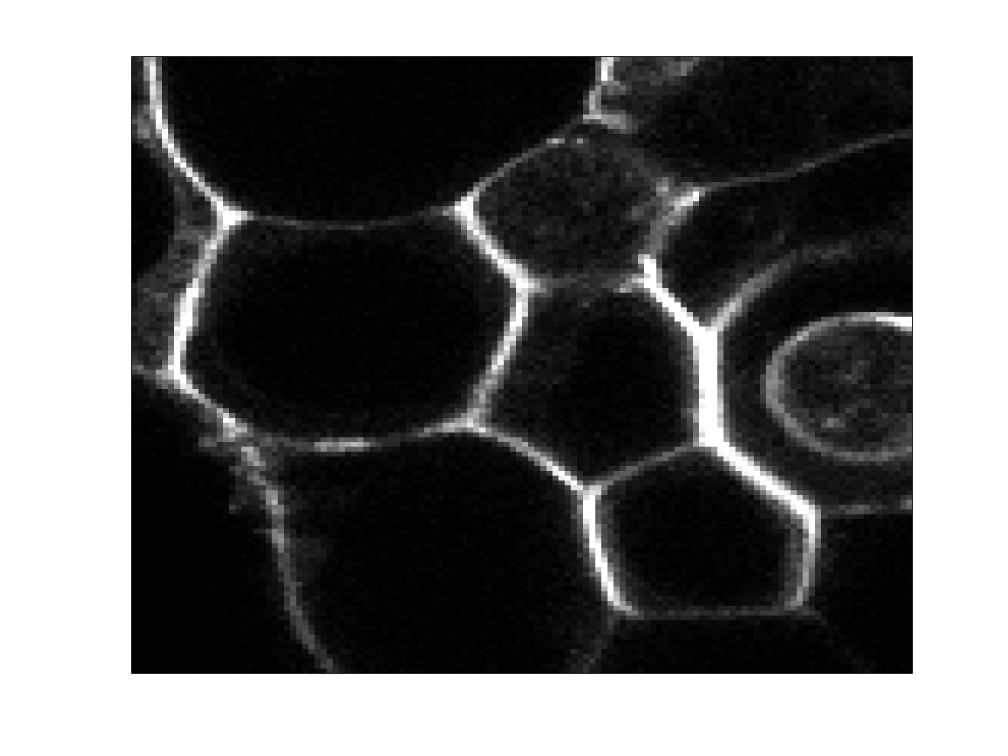

Ax=gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
h.ColorbarVisible='off';
h.GridVisible='off';
h.ColorLimits=[0 150];

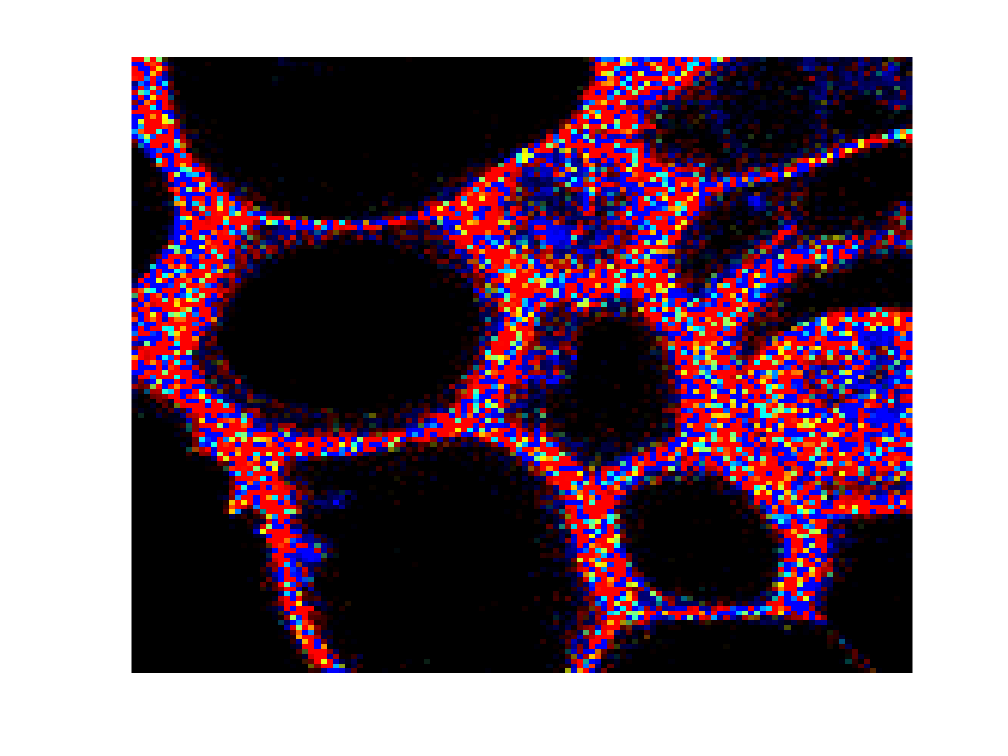

% low laser power, ACh, acq_num = 81

cyclePosition1_num = 38;

intensity_map = stateYao.images.origData.projects{2,1}(:,:,cyclePosition1_num);
Lifetime_rgb_map_81 = spc.rgbLifetimes{1};

figure
image(Lifetime_rgb_map_81);
axis off;


figure
h=heatmap(intensity_map);
h.Colormap=gray

h =   HeatmapChart with properties:

        XData: {128×1 cell}
        YData: {128×1 cell}
    ColorData: [128×128 double]

  Show all properties


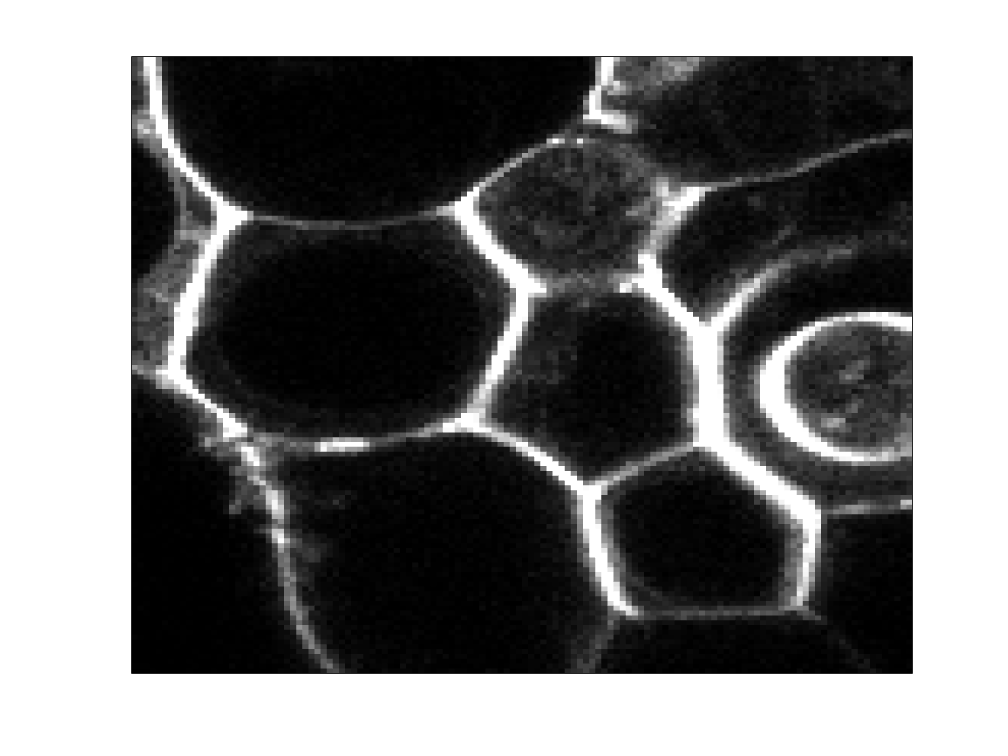

Ax=gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
h.ColorbarVisible='off';
h.GridVisible='off';
h.ColorLimits=[0 150];

datapath = ...
    {"/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Laser_power/20220518_AchsensorHEK002_laser/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Laser_power/20221024_AchsensorHEK002_laser",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Laser_power/20221024_AchsensorHEK003_laser/"...
    }

datapath = 1×3 cell array
    {["/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Laser_power/20220518_AchsensorHEK002_laser/"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Laser_power/20221024_AchsensorHEK002_laser"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Laser_power/20221024_AchsensorHEK003_laser/"]}




StateYao_file = ...
    {"analysis_offset0/20220518_AchsensorHEK002_Analysis2022-09-12.mat",...
    "analysis_offset0/20221024_AchsensorHEK002_Analysis2022-10-25.mat",...
    "Analysis_ROI_Correction_20230803.mat"...
    }

StateYao_file = 1×3 cell array
    {["analysis_offset0/20220518_AchsensorHEK002_Analysis2022-09-12.mat"]}    {["analysis_offset0/20221024_AchsensorHEK002_Analysis2022-10-25.mat"]}    {["Analysis_ROI_Correction_20230803.mat"]}




summary_files = {};

summary_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Laser_power'

summary_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Laser_power'

all_epochs = [2 3 4]; % all the epochs
drug_epochs = [2 3 4];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

CyclePositions = [1 2]

CyclePositions =      1     2


baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation
top_pixels = 1;
reference_acqn_num_all = {'020','022','024'};

FigureVisible = 'off'

FigureVisible = 'off'

% calculate the intensity from the top PMT imaging

for i = 3
    cd(datapath{i})
    load(StateYao_file{i})
    background_mask = background_mask_all{i};
    reference_acqn_num = reference_acqn_num_all{i}
    reference_image = [stateYao.baseName, reference_acqn_num, '.tif'];

    Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
    CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions)
    [lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
    [intensity_top, background] = CalcIntensity_topPMT(reference_image, top_pixels, background_mask, CyclePositions);
    [epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_top, lft_all, FigureVisible)

    currTime = datestr(datetime('now'));
    currTime = currTime(1:11);
    SavedFileName = [stateYao.baseName, '_', currTime,'_', num2str(CyclePositions(1)), '_',num2str(CyclePositions(2)),  '.mat'];
    summary_files{i} = SavedFileName;
    copyfile(SavedFileName, summary_path)

end

reference_acqn_num = '024'

epoch_response_intensity_norm_all = 1×2 cell array
    {2×5 double}    {2×5 double}


epoch_response_lft_norm_all = 1×2 cell array
    {2×5 double}    {2×5 double}


epoch_response_intensity_all = 1×2 cell array
    {2×5 double}    {2×5 double}


epoch_response_lft_all = 1×2 cell array
    {2×5 double}    {2×5 double}



cd(summary_path)
save('summary_files_topPMT.mat', 'summary_files')